# 'Continuum mechanics for tectonics

# Assignment (Week 7)

## Spring-slider exercises

We have derived the governing ODE and analytical solution for a linear velocity-dependant friction law applied to a spring-slider. For this section, you will have to derive the governing ODE and a solution for other popular friction/rheological laws.

The stress balance for a spring-slider is:


$$\frac{\textrm{d}}{\textrm{dt}}\left(f\sigma^‾ \right)=\left({\sigma^˙ }^{\infty \;} -\textrm{kv}\right)$$



$${\sigma^˙ }^{\infty \;} ={\mathrm{kv}}_{\mathrm{pl}}$$


- Power-law dependance, $f={\mathrm{Av}}^{\frac{1}{m}}$ : For $m=2$ derive the ODE and then solve it numerically for $A\sigma^‾ =0\ldotp 5,v_{\mathrm{pl}} =1,k=3$ subject to an initial condition $v\left(t=0\right)=v_i =100\;v_{\mathrm{pl}}$. Derive an analytical solution for $v\left(t\right),$ and compare the numerical solution to the analytical solution. If you are unable to integrate by hand, use MATLAB's symbolic toolbox or wolfram alpha to do this for you.

- Logarithmic dependance, $f=f_0 +A\;\mathrm{log}\left(\frac{v}{v_0 }\right)$: For the same set of parameters as above, solve the ODE analytically and numerically. 

- Compare all 3 functional forms (linear, power-law and log) and their solutions and discuss which solution decays the quickest? If you only had $v(t)$ for $t>0$, how would know which frictional law was applicable?

- For all 3 friction laws integrate the velocity solutions in time, and present the solution for slip as a function of time, $s(t)$.

## Stress change and sliding velocity 

The initial conditions in the above problem set was kinematically imposed. We can go one step further and use the friction laws to compute the velocity changes due to instantaneous stress changes, and use that as an initial condition. In other words, stress changes such as earthquakes, cause a sudden change in the sliding velocity of a frictional interface, and we can use the stress balance equations to calculate this instantaneous velocity change which then leads to a velocity evolution in time. To do this we must consider how stress change appears in the stress balance. Consider the case where an earthquake occurs at time $t_{\mathrm{eq}}$ with a stress change imparted to this interface $\Delta \tau_{\mathrm{eq}}$,

- just before the earthquake at $t_{\mathrm{eq}}^-$, 


$${\sigma^˙ }^{\infty \;} t_{\mathrm{eq}}^- -{\mathrm{ks}}^- =\sigma^‾ f\left(v^- \right)$$


- immediately after at $t_{\mathrm{eq}}^+$, 


$${\sigma^˙ }^{\infty \;} t_{\textrm{eq}}^+ -{\textrm{ks}}^+ +\Delta \tau_{\mathrm{eq}} =\sigma^‾ f\left(v^+ \right)$$


because $t_{\textrm{eq}}^-$ and $t_{\textrm{eq}}^+$ are essentially the same time (they refer to an inifinitesimal instant just before and after the earthquake), the fault has not slipped by much which means,


$$\Delta \tau_{\textrm{eq}} =\sigma^‾ \left(f\left(v^+ \right)-f\left(v^- \right)\right)$$


For each of the friction laws that you have encountered, (1) linear $v$-dependant, (2) power-law and (3) logarithmic dependance, derive the relationship between coseismic stress change $\Delta \tau_{\textrm{eq}}$ and the ratio $\frac{v^+ }{v^- }$.

## Earthquake cycle observations and inferring fault slip behaviour

The friction laws discussed above are directly relevant to fault zones. Instead of a single spring, fault zones can be thought of a large collection of inter-connected springs that can transfer stress to each other elastically. The fault patches close by receive greater stress transfer than distant patches, as we know from the Green's functions for stress. We model this interaction using a stress kernel or a Green's function matrix that relates slip on each patch to stress component at every other patch, and the coefficient is a function of distance between the patches. So $\left({\sigma^˙ }^{\infty \;} -\textrm{kv}\right)$still holds, except that each term is a vector with the number of elements equal to the total number of fault patches.

The following exercise is based on a simulation which incorporates the above idea for a 2-d strike-slip fault. The model generates earthquakes and a whole host of fault slip phenomena from interseismic creep to slow-slip events and earthquakes, as well as post-seismic relaxation. Your goal is to use a slice of synthetic observations generated by this model to infer the frictional properties of the fault.

## Coseismic displacements and slip

To start off, consider this earthquake that occurred on the fault and its surface displacement field.

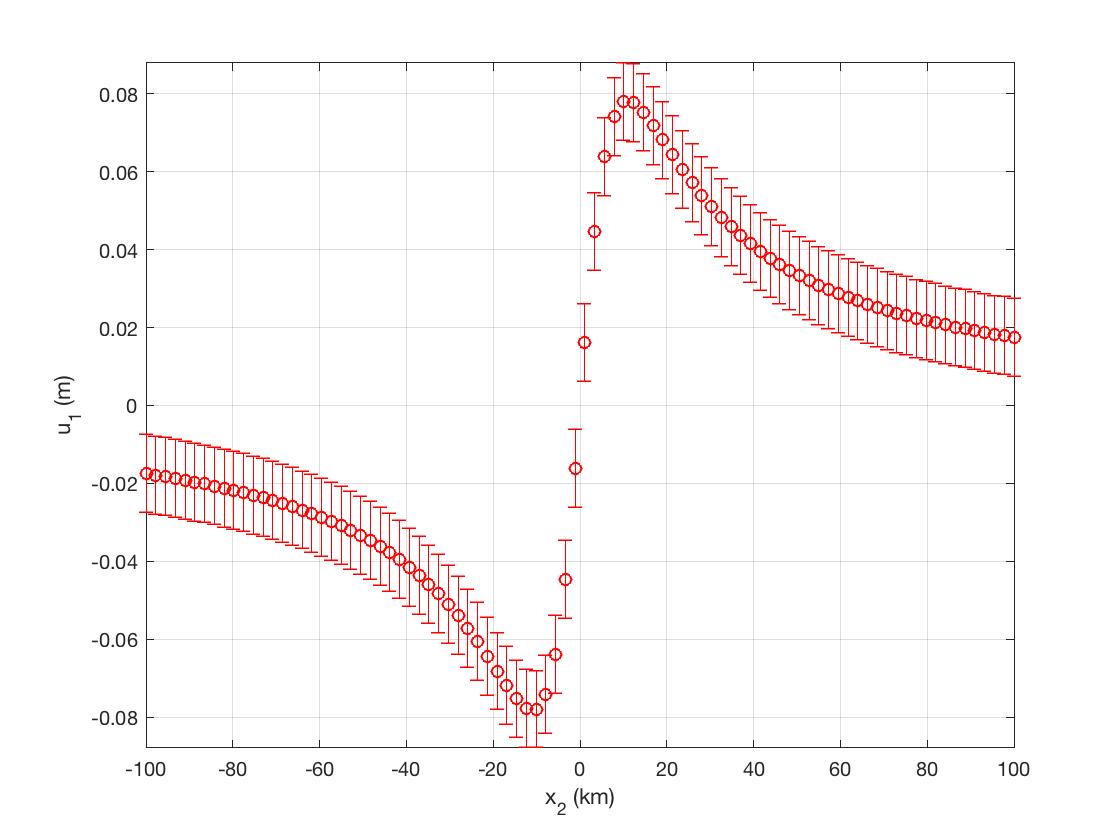

clear

eqobs = readtable('eq_displacement.dat');
ox = eqobs{:,1};% observation locations in meters
u1_eq = eqobs{:,2};% coseismic displacements in meters
% number of stations
nsta = length(ox);

figure(1),clf
errorbar(ox./1e3,u1_eq,0.01+0.*eqobs{:,2},'ro','MarkerSize',6)
axis tight, grid on
xlabel('x_2 (km)'), ylabel('u_1 (m)')

- Fit the displacement field using a slip model. The fault is located at $x_2 =0$ and is vertically dipping, and extends to 20 km deep into the crust. Since this is a mixed-determined problem, you will need to use apriori information such as regularization equations. In this case, use the finite-difference gradient operator $\left(s_{j+1} -s_j =0\right)$ to smooth your solution. 

## Interseismic and postseismic observations and slip

In addition to coseismic displacements, you also have the full timeseries from synthetic GPS stations. The locations are known to you from the coseismic displacement observations. This new dataset provides the displacement timeseries for each site over a period of ~2 years, 1 year before the earthquake and 1 year after the earthquake.

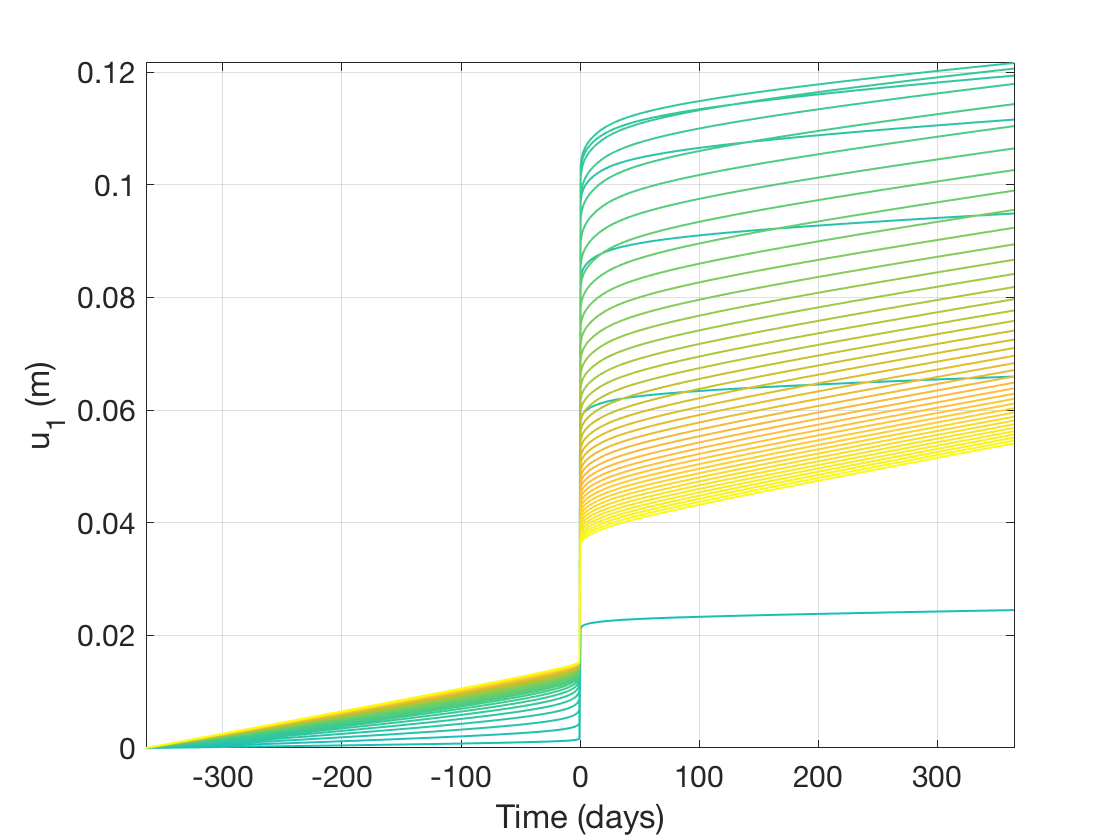

postobs = readtable('gps_timeseries.dat');
t = postobs{:,1};% in days
u1_post = postobs{:,2:end};% displacements in (m) for each station

cspec = parula(nsta);

figure(1),clf
for i = 46:nsta% plot only stations at x2>0
    plot(t,u1_post(:,i),'-','LineWidth',1,'Color',cspec(i,:)), hold on
end
axis tight, grid on
xlabel('Time (days)'), ylabel('u_1 (m)')
set(gca,'Fontsize',15)

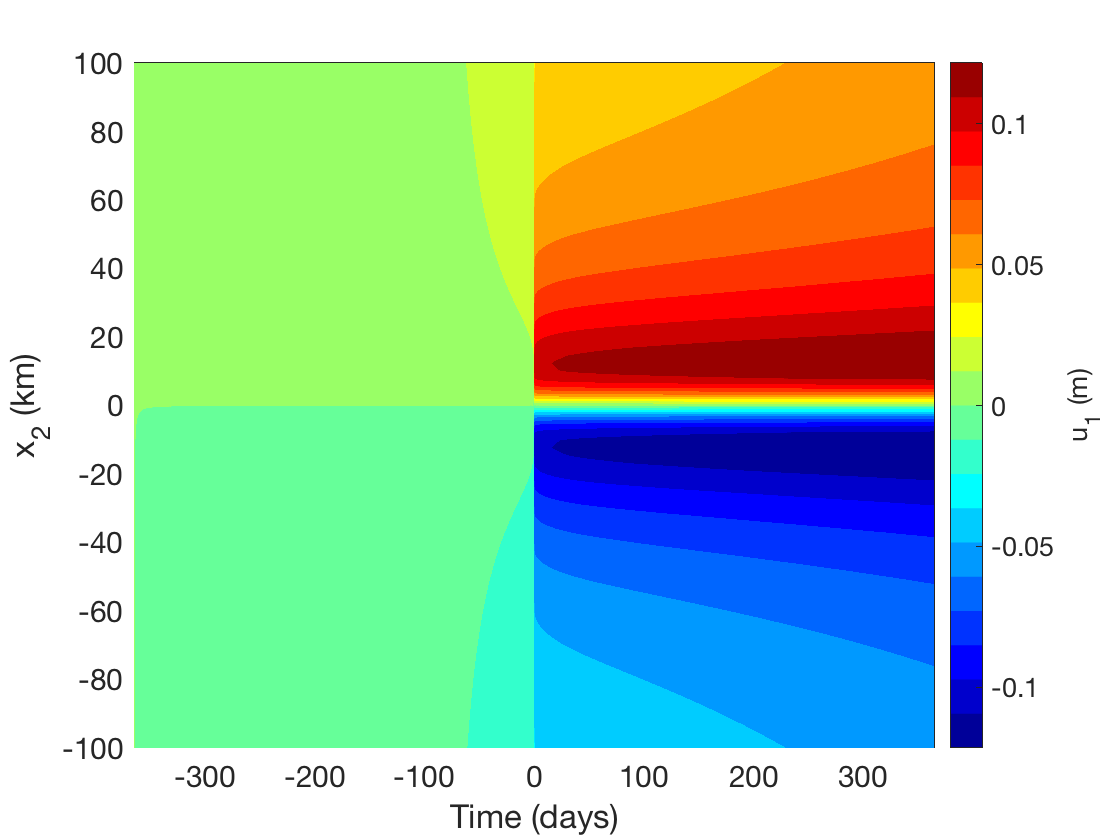

figure(2),clf
xind = ox~=0;
tind = t>-1000;
pcolor(t(tind),ox(xind)./1e3,u1_post(tind,xind)'), shading interp
cb = colorbar;cb.Label.String = 'u_1 (m)';
colormap(jet(20))
xlabel('Time (days)'), ylabel('x_2 (km)')
set(gca,'Fontsize',15)

- Use the time period before the earthquake $t<0$ to infer an interseismic velocity for each station, $v_{\mathrm{int}}$. Use your slip inversion technique (with regularization) to fit $v_{\textrm{int}}$ using a kinematic slip-deficit/coupling distribution. Recall that to simulate interseismic behaviour you have to add an arc-tangent function $\frac{V_{\mathrm{pl}} }{\pi }{\mathrm{tan}}^{-1} \frac{x_2 }{D}$, where $D=20$km is the locking depth. 

- For the time period following the earthquake, use sequential inversions for each epoch to estimate incremental slip on the fault. You may need to include a second regularization in time to stabilise the inverse problem. You can use the same gradient operator as you did in space, but just alter the indices to now relfect temporal smoothing. 

- Compare the locations of coseismic, interseismic and postseismic slip. What do you see?

- Using the postseismic observations, can you estimate what functional form governs fault slip? Estimate the coefficients for your choice of friction law.

- Use the stress change calculations from the coseismic slip distribution and the coefficients for your choice of friction law to estimate the velocity change from the interseismic to postseismic period on all the parts of the fault that did not slip in the earthquake. How does this compare to the kinematic inverse results?

- Bonus: Using a gridsearch, try to estimate the best-fitting spatially uniform coefficients for your choice of friction law. In other words, instead of doing a kinematic inversion, run a series of forward models (simulations of slip in time) with known initial velocity of each patch and coefficient and predict the dispalcements at the surface. Find the model with the least error and compare your model parameter estimates to what you got from kinematic inversion. Which method do you prefer, and why?